clear
clc

load('hall.mat');
[h,w] = size(hall_gray,[1 2]);
blockamountW = ceil(w/8);
blockamountH = ceil(h/8);
info = int32(randi([0 1],1,blockamountH*blockamountW));

隐藏信息

[ACstream,DCstream,h,w] = DCTconceal4(hall_gray,info);

提取信息

infoRtv = DCTretrieve4(ACstream,DCstream,h,w);

获取信息隐藏图像

ImageConceal = JpegDecoder(DCstream,ACstream,h,w);
subplot(1,2,2);
imshow(ImageConceal);
title('With Info');

计算PSNR

MSE = sum((ImageConceal-hall_gray).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

计算压缩率

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

评估信息还原的准确率

ErrorMtx = bitxor(info,infoRtv); % 按位异或得错误
fidelity = 1-sum(ErrorMtx,"all")/h/w; % 还原率

PSNR = 34.8004, 34.7905, 34,8042, 34.7862, 34.8115

compressrate = 6.3901, 6.3990, 6.3942, 6.3995, 6.39957

fidelity = 1, 1, 1, 1, 1

仅压缩对比

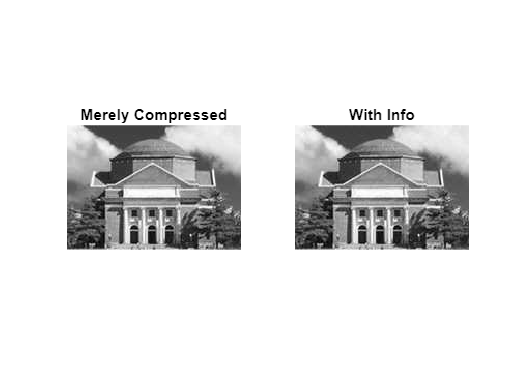

load("jpegcodes.mat");
ImageCompressed = JpegDecoder(DCstream,ACstream,h,w);
subplot(1,2,1);
imshow(ImageCompressed);
title('Merely Compressed');